Comparing plants of 0 added nose weight to 100kg added nose weight

Plant 1: 

0kg

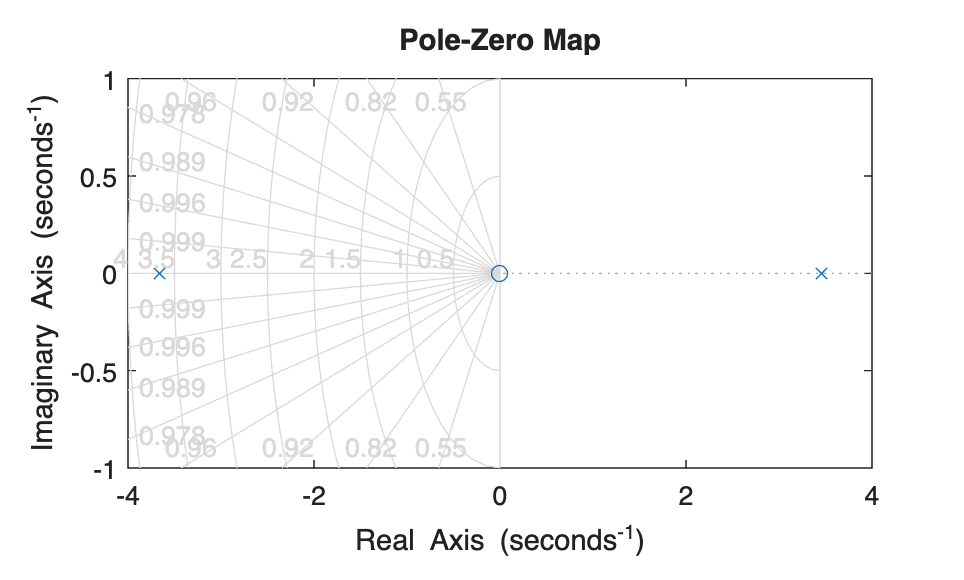

% 0kg Added nose weight
% Vehicle physical properties @ Max Q
T = 26540;        % Thrust (N)
l_CG = 4.74;     % Nozzle to CG distance (m)
I_y = 21846;      % Pitch moment of inertia (kg*m^2)
% Actuator hardware model
omega_act = 62;   % Actuator natural frequency (rad/s)
zeta_act = 0.505; % Actuator damping ratio

%% --- 2. Plant Definition ---
% --- 3) Dimensional derivatives ---
Malpha_maxQ =   277077;      % [N*m/rad]
Mq_maxQ     =   -4405;  % [N*m/(rad/s)]


% Gains per inertia
aero_gain_maxQ   = Malpha_maxQ / I_y;
mq_gain_maxQ     = Mq_maxQ / I_y;

% --- 4) Thrust-vector control gain ---
k_plant = T*l_CG/I_y;    % M_delta/I_y

% --- 5) Plants (q/δ) with damping included ---
num_plant = [k_plant 0];
den_maxQ   = [1, -mq_gain_maxQ,   -aero_gain_maxQ];

plant_maxQ   = tf(num_plant, den_maxQ);

